# Optimization for 1-D Phased Array

## Initialization

tstart = tic;
global x1 x2 x3 x4 x5 x6 x7 x8 y1 y2 y3 y4 y5 y6 y7 y8
c = physconst('LightSpeed');
freq = 2.4e9;
lambda = c/freq;
N = 8;
d = lambda/2;
Ns = 500;
Theta = linspace(-90,90,Ns);
% for N = 1:8
prob = optimproblem 

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


## Define optimization variables

% if N == 8
%% Amplitude
x1 = optimvar("x1","LowerBound",0,"UpperBound",1)

x1 =   OptimizationVariable with properties:

          Name: 'x1'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: 0
    UpperBound: 1

  See variables with show.
  See bounds with showbounds.


x2 = optimvar("x2","LowerBound",0,"UpperBound",1)

x2 =   OptimizationVariable with properties:

          Name: 'x2'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: 0
    UpperBound: 1

  See variables with show.
  See bounds with showbounds.


x3 = optimvar("x3","LowerBound",0,"UpperBound",1)

x3 =   OptimizationVariable with properties:

          Name: 'x3'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: 0
    UpperBound: 1

  See variables with show.
  See bounds with showbounds.


x4 = optimvar("x4","LowerBound",0,"UpperBound",1)

x4 =   OptimizationVariable with properties:

          Name: 'x4'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: 0
    UpperBound: 1

  See variables with show.
  See bounds with showbounds.


x5 = optimvar("x5","LowerBound",0,"UpperBound",1)

x5 =   OptimizationVariable with properties:

          Name: 'x5'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: 0
    UpperBound: 1

  See variables with show.
  See bounds with showbounds.


x6 = optimvar("x6","LowerBound",0,"UpperBound",1)

x6 =   OptimizationVariable with properties:

          Name: 'x6'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: 0
    UpperBound: 1

  See variables with show.
  See bounds with showbounds.


x7 = optimvar("x7","LowerBound",0,"UpperBound",1)

x7 =   OptimizationVariable with properties:

          Name: 'x7'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: 0
    UpperBound: 1

  See variables with show.
  See bounds with showbounds.


x8 = optimvar("x8","LowerBound",0,"UpperBound",1)

x8 =   OptimizationVariable with properties:

          Name: 'x8'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: 0
    UpperBound: 1

  See variables with show.
  See bounds with showbounds.



%% Initial phase
y1 = optimvar("y1","LowerBound",-90,"UpperBound",90)

y1 =   OptimizationVariable with properties:

          Name: 'y1'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -90
    UpperBound: 90

  See variables with show.
  See bounds with showbounds.


y2 = optimvar("y2","LowerBound",-90,"UpperBound",90)

y2 =   OptimizationVariable with properties:

          Name: 'y2'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -90
    UpperBound: 90

  See variables with show.
  See bounds with showbounds.


y3 = optimvar("y3","LowerBound",-90,"UpperBound",90)

y3 =   OptimizationVariable with properties:

          Name: 'y3'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -90
    UpperBound: 90

  See variables with show.
  See bounds with showbounds.


y4 = optimvar("y4","LowerBound",-90,"UpperBound",90)

y4 =   OptimizationVariable with properties:

          Name: 'y4'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -90
    UpperBound: 90

  See variables with show.
  See bounds with showbounds.


y5 = optimvar("y5","LowerBound",-90,"UpperBound",90)

y5 =   OptimizationVariable with properties:

          Name: 'y5'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -90
    UpperBound: 90

  See variables with show.
  See bounds with showbounds.


y6 = optimvar("y6","LowerBound",-90,"UpperBound",90)

y6 =   OptimizationVariable with properties:

          Name: 'y6'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -90
    UpperBound: 90

  See variables with show.
  See bounds with showbounds.


y7 = optimvar("y7","LowerBound",-90,"UpperBound",90)

y7 =   OptimizationVariable with properties:

          Name: 'y7'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -90
    UpperBound: 90

  See variables with show.
  See bounds with showbounds.


y8 = optimvar("y8","LowerBound",-90,"UpperBound",90)

y8 =   OptimizationVariable with properties:

          Name: 'y8'
          Type: 'continuous'
    IndexNames: {{}  {}}
    LowerBound: -90
    UpperBound: 90

  See variables with show.
  See bounds with showbounds.


## Import objective function with all variables

edit objfun_1D
obj = fcn2optimexpr(@objfun_1D,x1,x2,x3,x4,x5,x6,x7,x8,y1,y2,y3,y4,y5,y6,y7,y8)

    1.1821

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0009    0.0013    0.0018    0.0024    0.0031    0.0041    0.0052    0.0065    0.0080    0.0099    0.0120    0.0144    0.0172    0.0204    0.0239    0.0280    0.0325    0.0375    0.0430    0.0492    0.0559    0.0633    0.0713    0.0801    0.0896    0.0999    0.1110    0.1230    0.1358    0.1494    0.1640    0.1795    0.1959    0.2132    0.2316    0.2508    0.2710    0.2922    0.3143    0.3372    0.3611    0.3858    0.4113    0.4376    0.4645    0.4921    0.5203    0.5489    0.5780    0.6073    0.6368    0.6664    0.6959    0.7253    0.7543    0.7828    0.8107    0.8378    0.8640    0.8890    0.9128    0.9350    0.9556    0.9744    0.9912    1.0057    1.0180    1.0277    1.0347    1.0389    1.0402    1.0384    1.0335    1.0254    1.0139    0.9991    0.9810    0.9595    0.9348    0.9068    0.8758    0.8418    0.8049    0.7655    0.7237    0.6799    0.6342    0.58

obj =   Nonlinear OptimizationExpression

    objfun_1D(x1, x2, x3, x4, x5, x6, x7, x8, y1, y2, y3, y4, y5, y6, y7, y8)


prob.Objective = obj

prob =   OptimizationProblem with properties:

       Description: ''
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 16 OptimizationVariables
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.


## Set initial value

%% all initial value is the mid point of the operation
x0.x1 = 0.5;
x0.x2 = 0.5;
x0.x3 = 0.5;
x0.x4 = 0.5;
x0.x5 = 0.5;
x0.x6 = 0.5;
x0.x7 = 0.5;
x0.x8 = 0.5;

x0.y1 = 0;
x0.y2 = 0;
x0.y3 = 0;
x0.y4 = 0;
x0.y5 = 0;
x0.y6 = 0;
x0.y7 = 0;
x0.y8 = 0;
% end
% if N == 2
%     x1 = optimvar("x1","LowerBound",0,"UpperBound",1)
% x2 = optimvar("x2","LowerBound",0,"UpperBound",1)
% 
% y1 = optimvar("y1","LowerBound",-90,"UpperBound",90)
% y2 = optimvar("y2","LowerBound",-90,"UpperBound",90)
% 
% 
% edit objfun_1D_2
% obj = fcn2optimexpr(@objfun_1D_2,x1,x2,y1,y2)
% prob.Objective = obj
% 
% x0.x1 = 0.5;
% x0.x2 = 0.5;
% 
% x0.y1 = 0;
% x0.y2 = 0;
% end
% end

## Call the solver

[sol,fval,exitflag] = solve(prob,x0)

Solving problem using fmincon.
    1.1821

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0004    0.0006    0.0009    0.0013    0.0018    0.0024    0.0031    0.0041    0.0052    0.0065    0.0080    0.0099    0.0120    0.0144    0.0172    0.0204    0.0239    0.0280    0.0325    0.0375    0.0430    0.0492    0.0559    0.0633    0.0713    0.0801    0.0896    0.0999    0.1110    0.1230    0.1358    0.1494    0.1640    0.1795    0.1959    0.2132    0.2316    0.2508    0.2710    0.2922    0.3143    0.3372    0.3611    0.3858    0.4113    0.4376    0.4645    0.4921    0.5203    0.5489    0.5780    0.6073    0.6368    0.6664    0.6959    0.7253    0.7543    0.7828    0.8107    0.8378    0.8640    0.8890    0.9128    0.9350    0.9556    0.9744    0.9912    1.0057    1.0180    1.0277    1.0347    1.0389    1.0402    1.0384    1.0335    1.0254    1.0139    0.9991    0.9810    0.9595    0.9348    0.9068    0.8758    0.8418    0.8049    0.7655    0.7

sol = struct with fields:
    x1: 1.0000
    x2: 1.0000
    x3: 1.0000
    x4: 1.0000
    x5: 1.0000
    x6: 1.0000
    x7: 1.0000
    x8: 1.0000
    y1: 3.9230e-07
    y2: 3.1261e-06
    y3: 1.9818e-06
    y4: 8.4623e-07
    y5: 5.4304e-08
    y6: -2.5151e-06
    y7: -2.3637e-07
    y8: 1.8702e-06


fval = -140.9416

exitflag =     StepSizeBelowTolerance


## Save Result

save_x = [sol.x1 sol.x2 sol.x3 sol.x4 sol.x5 sol.x6 sol.x7 sol.x8]

save_x =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


save_y = [sol.y1 sol.y2 sol.y3 sol.y4 sol.y5 sol.y6 sol.y7 sol.y8]

save_y = 1.0e-05 *

    0.0392    0.3126    0.1982    0.0846    0.0054   -0.2515   -0.0236    0.1870


## Plot

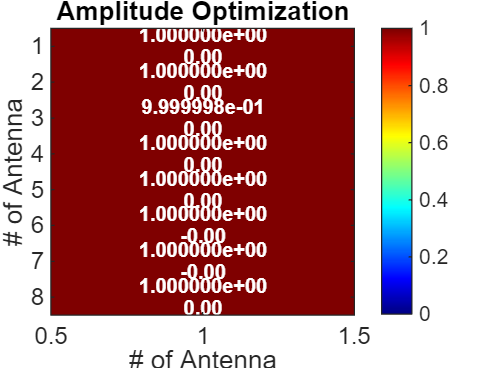

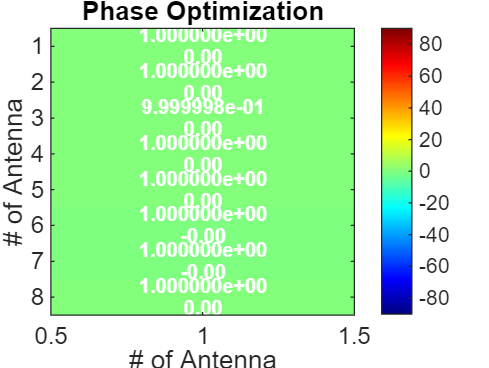

getColordiagram1D(save_x,save_y)

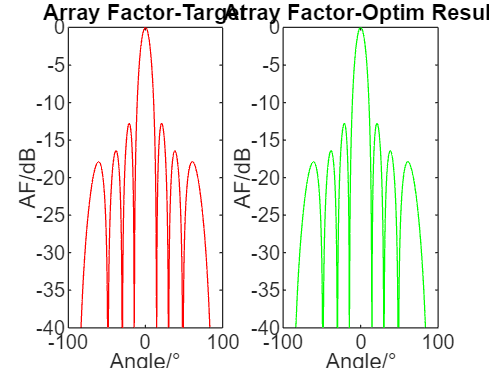

AFx = getBeam(save_x,Theta,lambda,save_y,d,N);
save("AFx.mat");
load("AF1.mat")
AF1_max = max(AF1);
AFx_max = max(AFx);

figure()
subplot(1,2,1)
plot(Theta, 20*log10(abs(AFx)/abs(AFx_max)), 'r');
title('Array Factor-Target');
xlabel(['Angle/' char(176)]);
ylabel('AF/dB');
ylim([-40,0])

subplot(1,2,2)
plot(Theta, 20*log10(abs(AF1)/abs(AF1_max)), 'g');
title('Array Factor-Optim Result');
xlabel(['Angle/' char(176)]);
ylabel('AF/dB');
ylim([-40,0])


disp(['Difference = ' num2str(fval) ' dB']);

Difference = -140.9416 dB


## Time count

t = toc(tstart);
disp(['Time(s): ', num2str(t),' sec'])

Time(s): 8.6584 sec


disp(['Time(min): ', num2str(t/60),' min'])

Time(min): 0.14431 min
